# 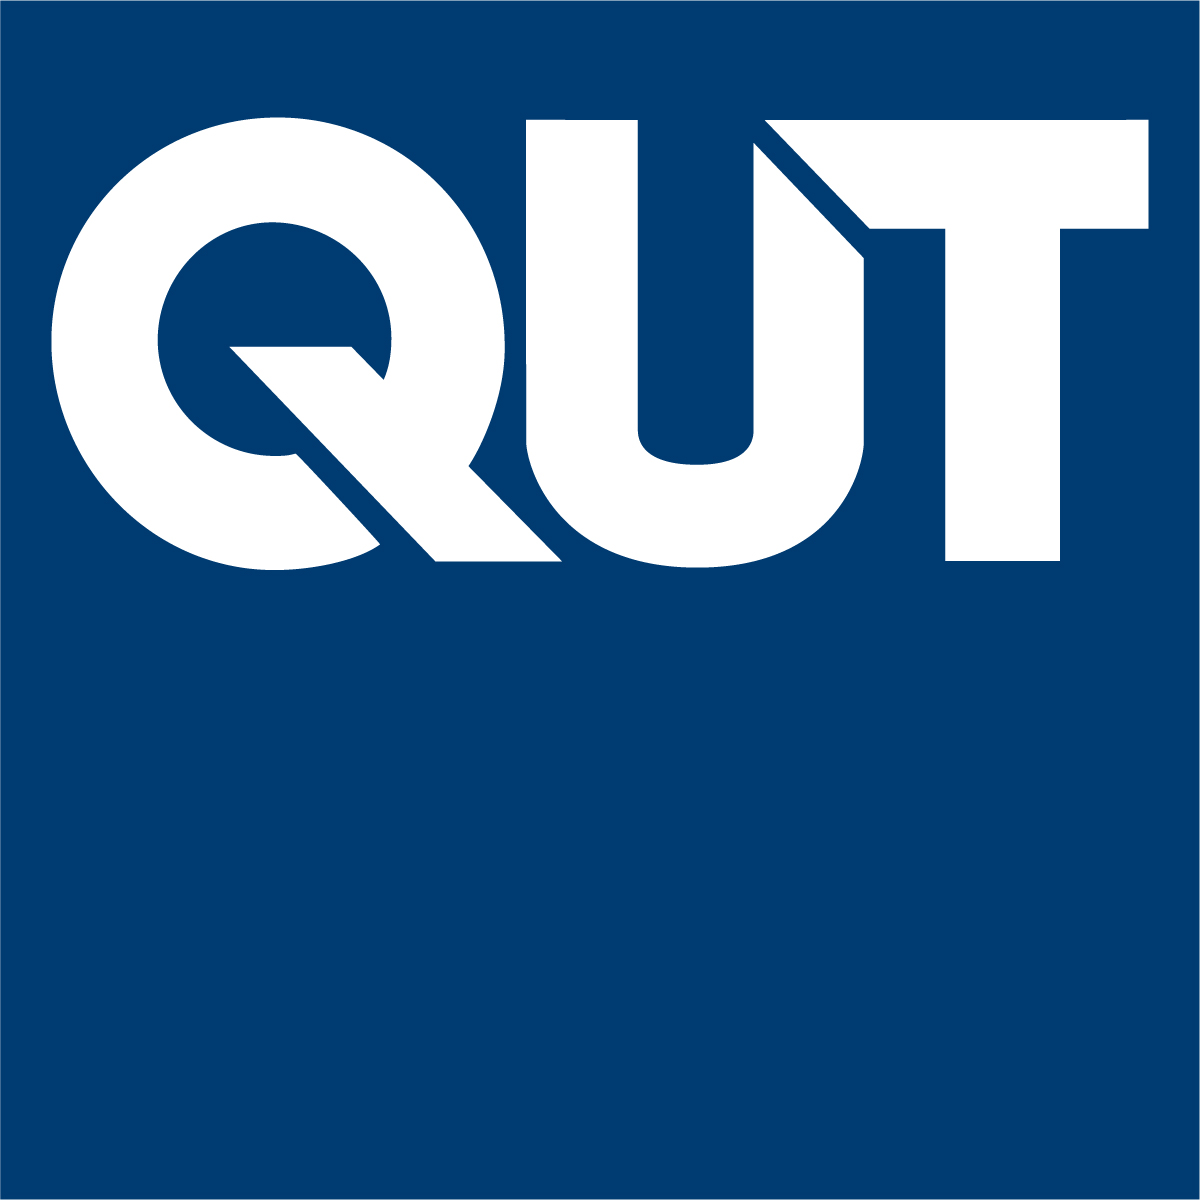

# MXB201 Linear Algebra in the Real World™ Series

Professor Tim Moroney,  2022

V1.0

## Climate Change in Australia

Linear Algebra prerequisites:

- Least squares model fitting

### Introduction

Is the climate in Australia changing?  Are temperatures today much different than they were 50 years ago?  Let's use linear algebra to investigate!

Our methodology will be to analyse the records of the *daily maximum temperature* at a location in Australia, over a period of around 50 years.  We will endeavour to fit a mathematical model that captures the key trends in this record, and from that ascertain whether there has been any significant change over that period.

First up, let's look at the data for one particular weather station.  We're using the [Climate Data Online](http://www.bom.gov.au/climate/data/?ref=ftr) facility of the Bureau of Meteorology.  The MATLAB function `read_bom_temperature_data` (that we provided) will download the data from the provided URL, and strip out any days for which there was no measurement recorded.

clear
url = 'http://www.bom.gov.au/jsp/ncc/cdio/weatherData/av?p_display_type=dailyZippedDataFile&p_stn_num=036031&p_c=-259656235&p_nccObsCode=122&p_startYear=2022'

url = 'http://www.bom.gov.au/jsp/ncc/cdio/weatherData/av?p_display_type=dailyZippedDataFile&p_stn_num=036031&p_c=-259656235&p_nccObsCode=122&p_startYear=2022'

[t, T, station_info] = read_bom_temperature_data(url)

t =       -20488
      -20487
      -20486
      -20485
      -20483
      -20482
      -20481
      -20480
      -20479
      -20478


T =    41.0000
   39.8000
   39.3000
   35.0000
   35.0000
   35.7000
   34.8000
   35.7000
   37.2000
   37.8000


station_info = struct with fields:
        range: [01-Mar-1966    04-Apr-2022]
         name: 'LONGREACH AERO'
     latitude: -23.4400
    longitude: 144.2800


**(In case the download fails for some reason, the file **`longreach.mat`** provided with this worksheet has the same data.)**

% load longreach       %%%% uncomment this line only if read_bom_temperature_data fails

You can see you get back the maximum temperature `T` for each day `t`, where `t` is measured counting backwards from the present (so t` = 0` means the most recent measurement taken).  You also get a structure containing information about the station, including the range of time the records span, the station's name, and its geographic location.

**Because we are working with data from the Real World™, we are using floating point arithmetic for this prac.**  All the measurements printed above are floating point values.  Aside from being much faster to compute with, using floating point rather than symbolic arithmetic for this problem actually has a further beneficial side-effect which we'll highlight when it comes up.

Let's plot the data.

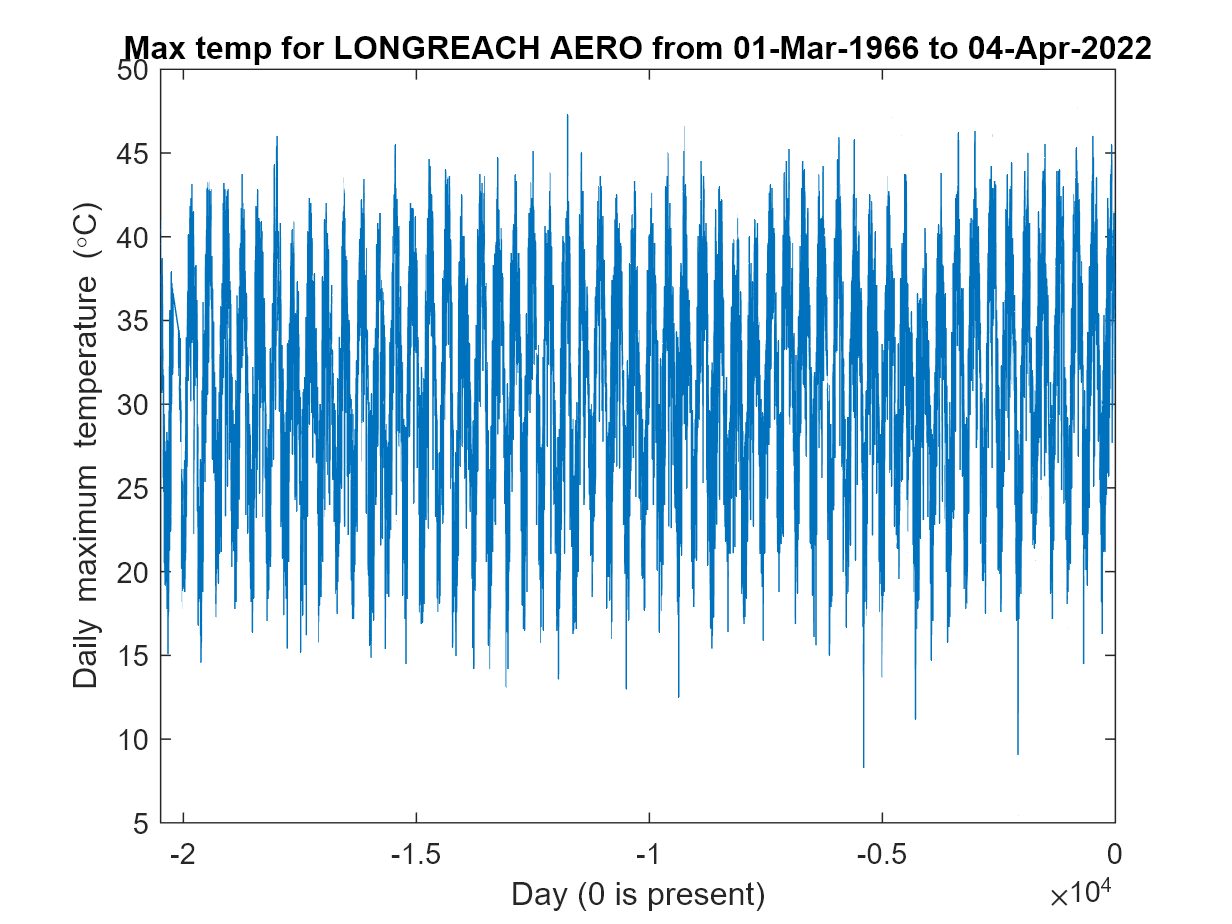

figure
plot(t, T)
xlabel('Day (0 is present)')
ylabel('Daily maximum temperature (\circC)')
title_str = "Max temp for " + station_info.name ...
          + " from " + datestr(station_info.range(1)) ...
          + " to " + datestr(station_info.range(2));
title(title_str)
xlim([min(t), max(t)])

It's hard to make out too much from such a range of data, although the oscillatory nature of the measurements is obvious.  Let's zoom in on just the last five years.

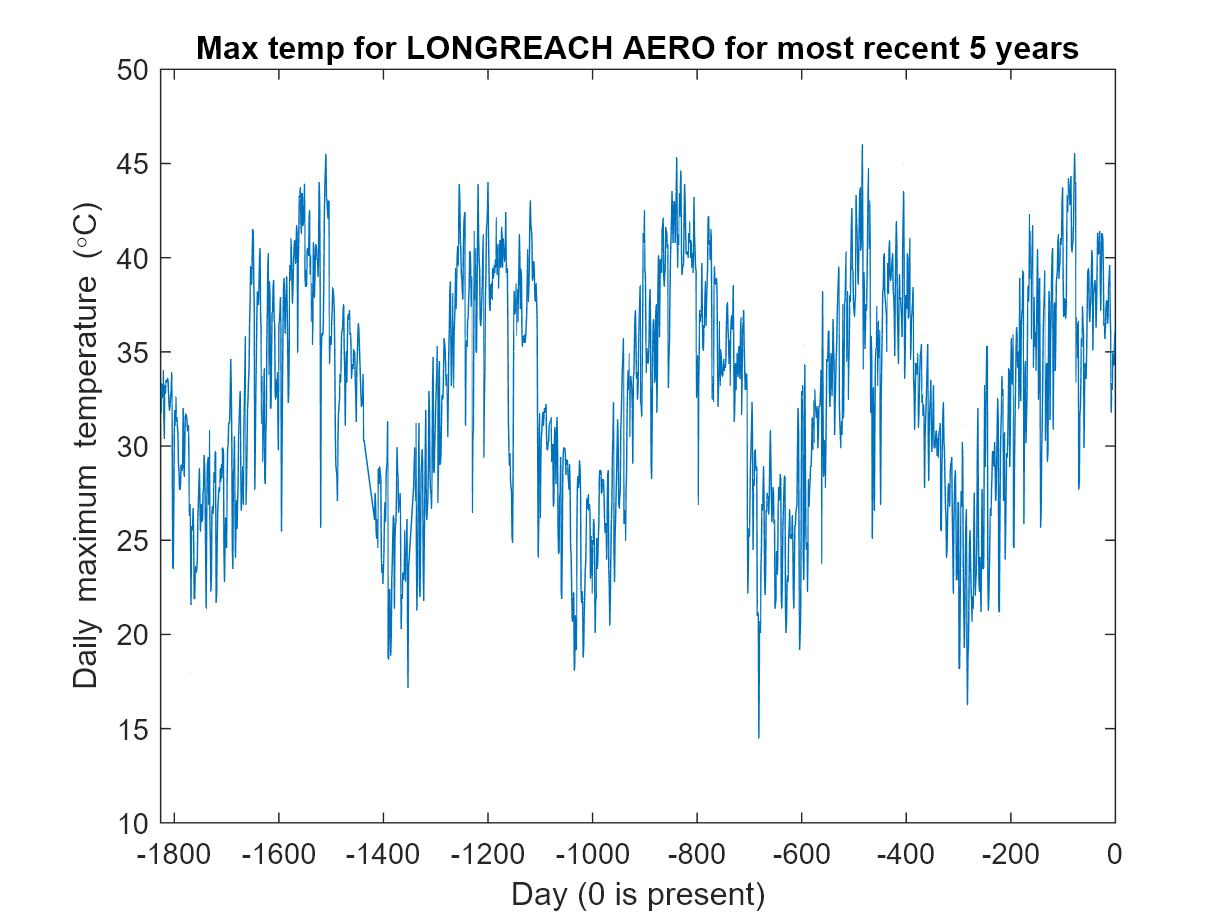

xlim([-365.24*5, 0])
title("Max temp for " + station_info.name + " for most recent 5 years")

Now we see the oscillatory temperature fluctuations clearly, albeit with considerable noise.  What isn't clear just by looking is whether there's a gradual drift of the temperature over this period.  For that investigation, we should fit a suitable mathematical model over the full duration of the data.

### **Group Discussion: What is a suitable model?**

Our input data are pairs of measurements $(t_i\,, T_i)$ taken from a particular weather station over a period of some decades, although not necessarily exactly 50 years (could be more, could be less).  Time $t_i$ is measured in days (as integers, counting backwards from the present), and $T_i$ is the maximum temperature recorded for that day.  Any days, or ranges of days, that had missing data have been removed.

We will propose a mathematical model


$$T = f(t)$$


for some sensibly-chosen functional form $f(t)$.  You'll need to decide what form of $f(t)$ makes sense for this kind of data.  Keep in mind what type of variation we *know *will exist in the data (i.e. seasonal oscillations), and what type of variation we are investigating (i.e. is there a gradual drift of the temperature over time, independent of seasonal oscillations).  And of course, coming from the Real World™, the data will be noisy.

**What is a suitable functional form **$f(t)$?


$$f\left(t\right)=\sum_{n=1} a_n \cos \left(n*t\right)+b_n \sin \left(n*t\right)+a_0 +c*t$$



$$f\left(t\right)=c_1 \sin \left(2\pi f\;t\right)+c_2 \cos \left(2\pi f\;t\right)+c_3 t+c_4$$


**What aspect of the model would indicate the amount by which the temperature has changed over 50 years?**

The linear term as it has units of T/t

Once you have the model sorted out, go ahead and fit the model to the data you've been provided for Longreach Aero using least squares.

**Question A1 from Exercises 2 will be a good reference for this step.**

period = 365.25;
n = length(t);
f = 1 / period;
A = [sin(2 * pi * f * t) cos(2 * pi * f * t) t ones([n 1])]

A = 1.0e+04 *

   -0.0001    0.0001   -2.0488    0.0001
   -0.0001    0.0001   -2.0487    0.0001
   -0.0001    0.0001   -2.0486    0.0001
   -0.0001    0.0001   -2.0485    0.0001
   -0.0000    0.0001   -2.0483    0.0001
   -0.0000    0.0001   -2.0482    0.0001
   -0.0000    0.0001   -2.0481    0.0001
   -0.0000    0.0001   -2.0480    0.0001
   -0.0000    0.0001   -2.0479    0.0001
   -0.0000    0.0001   -2.0478    0.0001


**Important MATLAB shortcut:  **When your arrays $A$ and $b$ are stored using **floating point **representations, MATLAB is perfectly happy to "solve" $Ax = b$ even when $A$ is rectangular and $b$ is not in the column space.  Under those circumstances, the command `A\b` returns the least squares solution, which is exactly what you want.  So you don't need to form the normal equations or anything like that.  Just build your rectangular matrix $A$, your right hand side $b$, and hit it with backslash.  (This isn't true if $A$ and $b$ are *symbolic* arrays -- in that case MATLAB plays by the book and insists that if you want least squares solutions in symbolic arithmetic, that you should do so explicitly by forming the normal equations yourself.)

Plot the fitted model over the top of the BOM data.  For Longreach Aero, you might obtain a model fit something like the one shown below.  Make sure yours looks sensible before proceeding any further.

t_sol = A \ T

t_sol =    -7.0247
    0.0241
    0.0001
   32.2469


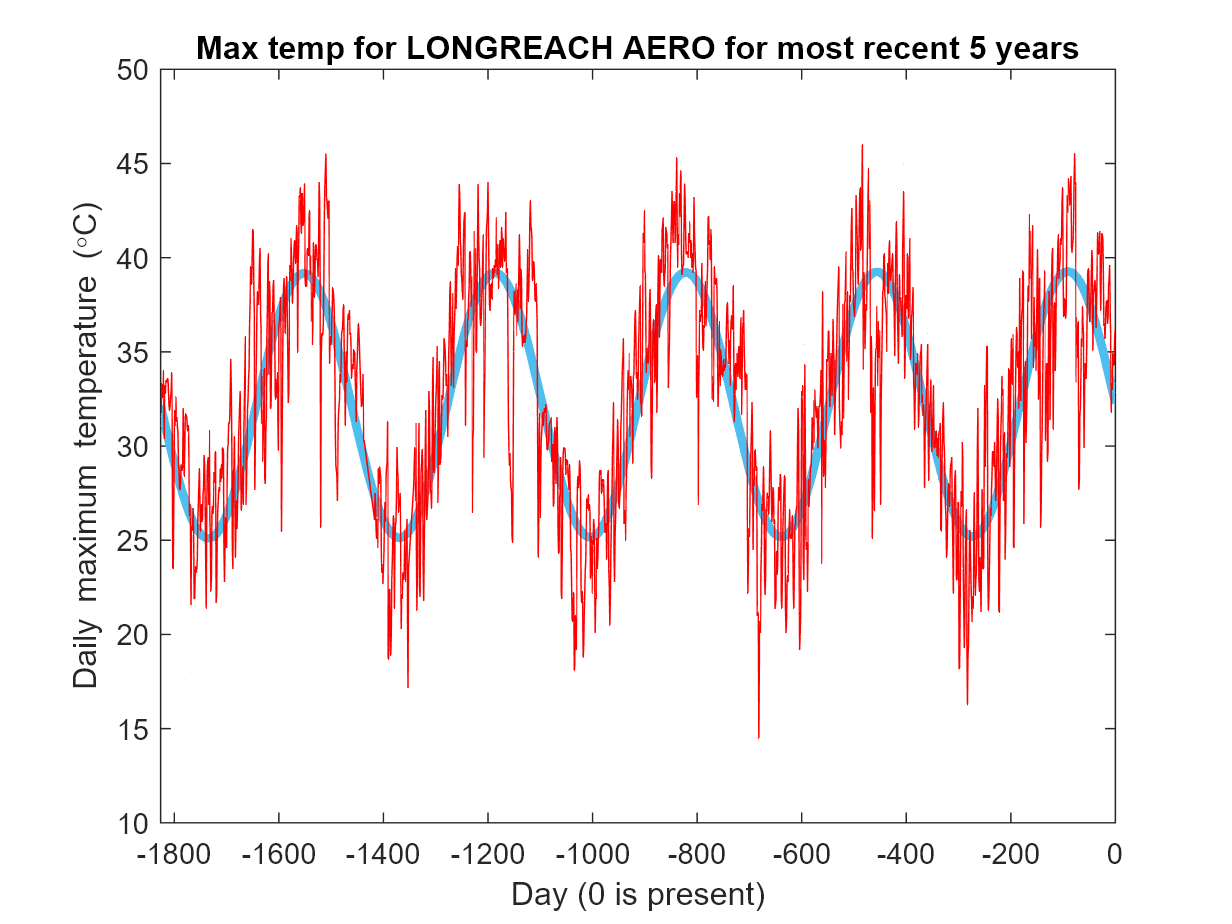

hold on, fplot(@(t_var) t_sol(1)*sin(2 * pi * f * t_var) + t_sol(2)*cos(2 * pi * f * t_var) + t_sol(3)*t_var + t_sol(4),LineWidth=3)
plot(t,ifft(fft(T)), 'r', LineWidth=0.5)

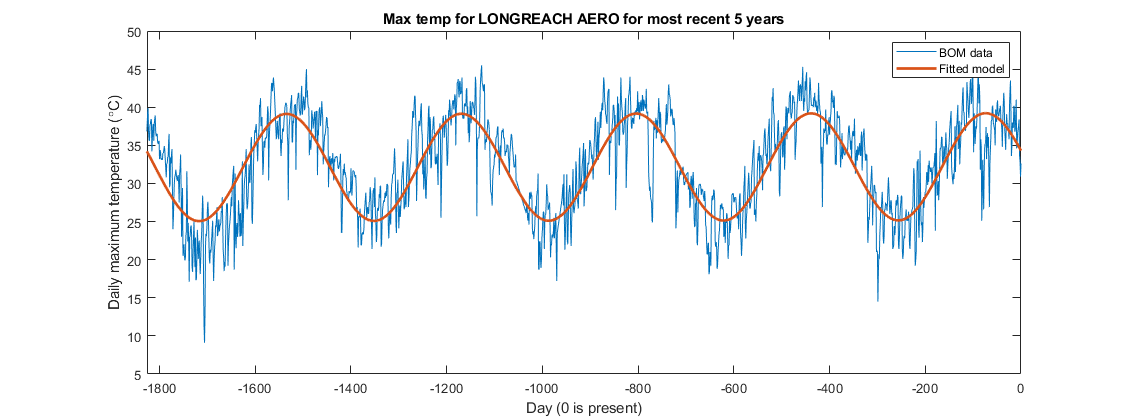

Using the information contained in your fitted model, calculate a sensible answer to the question:

**By how much has the temperature at Longreach Aero changed over the last 50 years?**

celsius_change_per_day = t_sol(3);
days_per_50_years = 50 * 365.25;
changeIn_50_years = celsius_change_per_day * days_per_50_years

changeIn_50_years = 1.2367

For comparison, the answer I obtained when fitting to this same data was around 1.2 degrees.

### Crowdsourcing the data

Now it's time for everyone to pick their own location in Australia!  Jump onto the BOM website, at [http://www.bom.gov.au/climate/data/?ref=ftr](http://www.bom.gov.au/climate/data/?ref=ftr) .

Select Map search.

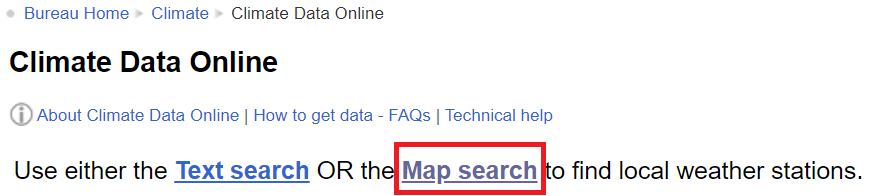

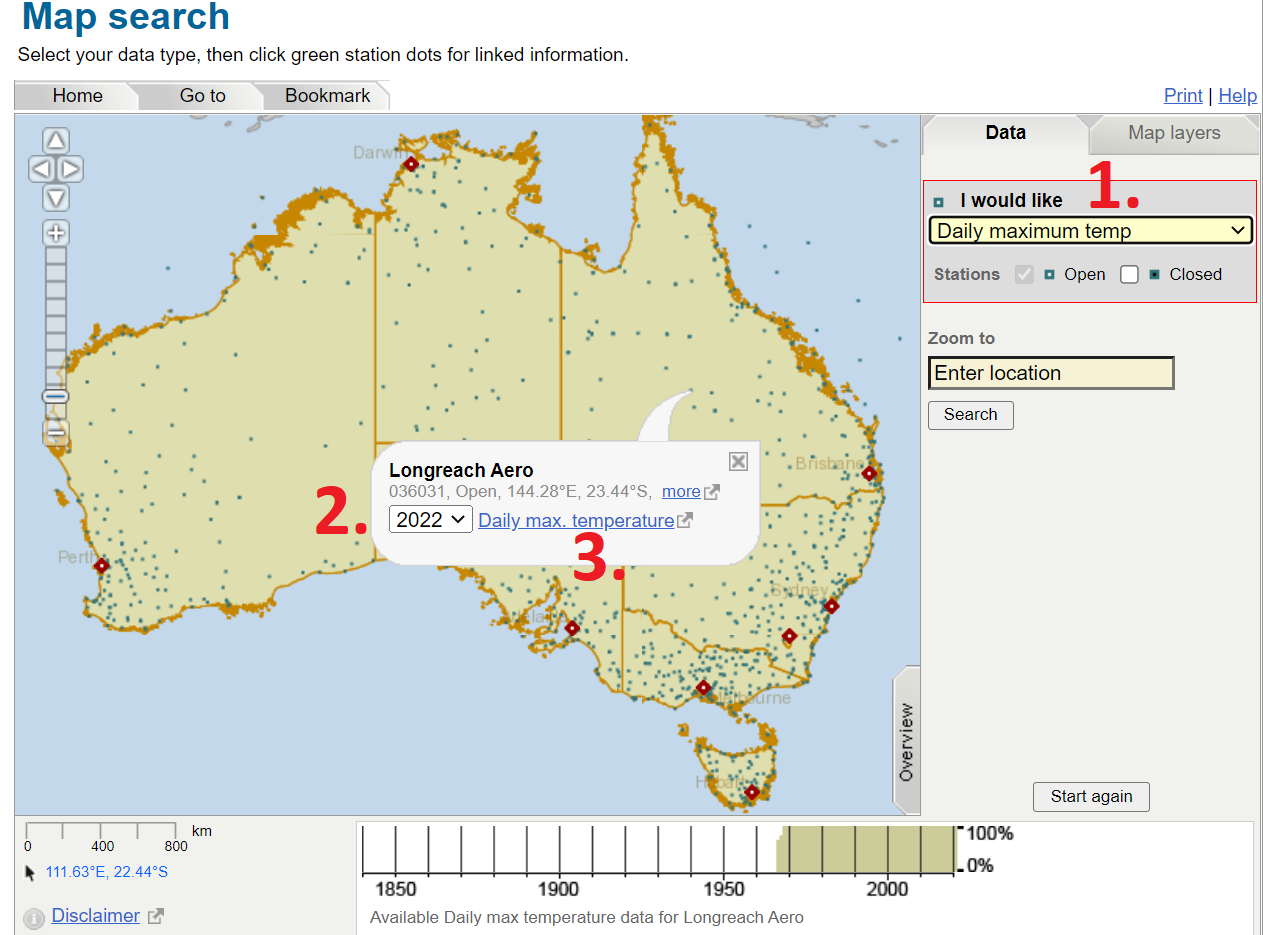

See the image above.  You want to:

- I would like: Daily maximum temp

- Then click an interesting looking location on the map, and check it's got data for around 50 years, up to 2021.  (At a pinch, even around 30 years of data would probably suffice to get the trend.)

- Click Daily max. temperature

**Please don't pick somewhere in Tasmania.  We plan to make a heatmap of all the results, and I don't want the headache of dealing with a disconnected domain.  Sorry Tassie.**

In the next window that opens, right click and copy the link to All years of data.

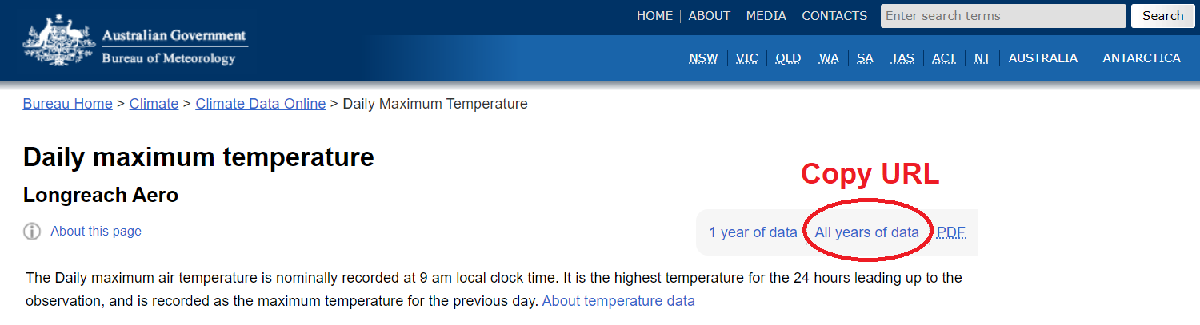

That URL is exactly what you want to provide to the function `read_bom_temperature_data` like we saw earlier.  Give it a try now, and check that it reads in your data alright.

clear
url = "http://www.bom.gov.au/jsp/ncc/cdio/weatherData/av?p_display_type=dailyZippedDataFile&p_stn_num=003030&p_c=-1845823&p_nccObsCode=122&p_startYear=2022"

url = "http://www.bom.gov.au/jsp/ncc/cdio/weatherData/av?p_display_type=dailyZippedDataFile&p_stn_num=003030&p_c=-1845823&p_nccObsCode=122&p_startYear=2022"

If all is well, then go ahead and refit your model to the data from your chosen location.  Check that the figure comes out looking right, and then calculate your model's prediction for the temperature change at your location over the last 50 years.

**Even if your data doesn't span exactly 50 years (and it very likely won't), the measurement we're all agreeing to use is temperature change over 50 years.  So scale your answer appropriately so it's measuring the change over a period of exactly 50 years.**

[t, T, station_info] = read_bom_temperature_data(url)

t =       -23833
      -23832
      -23831
      -23830
      -23829
      -23828
      -23827
      -23826
      -23825
      -23824


T =   32.799999999999997
  32.799999999999997
  33.299999999999997
  33.299999999999997
  32.799999999999997
  32.799999999999997
  33.299999999999997
  33.299999999999997
  33.299999999999997
  36.100000000000001


station_info = struct with fields:
        range: [01-Jan-1957    03-Apr-2022]
         name: 'BIDYADANGA'
     latitude: -18.680000000000000
    longitude: 1.217800000000000e+02


figure
plot(t, T)
xlabel('Day (0 is present)')
ylabel('Daily maximum temperature (\circC)')
title_str = "Max temp for " + station_info.name ...
          + " from " + datestr(station_info.range(1)) ...
          + " to " + datestr(station_info.range(2));
title(title_str)
xlim([min(t), max(t)])

xlim([-365.24*5, 0])
title("Max temp for " + station_info.name + " for most recent 5 years")

period = 365.25;
n = length(t);
f = 1 / period;
A = [sin(2 * pi * f * t) cos(2 * pi * f * t) t ones([n 1])]

A = 1.0e+04 *

  -0.000099997167934  -0.000000752598938  -2.383300000000000   0.000100000000000
  -0.000099995318436   0.000000967621241  -2.383200000000000   0.000100000000000
  -0.000099963878715   0.000002687555085  -2.383100000000000   0.000100000000000
  -0.000099902858073   0.000004406693638  -2.383000000000000   0.000100000000000
  -0.000099812274569   0.000006124528180  -2.382900000000000   0.000100000000000
  -0.000099692155006   0.000007840550376  -2.382800000000000   0.000100000000000
  -0.000099542534931   0.000009554252426  -2.382700000000000   0.000100000000000
  -0.000099363458619   0.000011265127220  -2.382600000000000   0.000100000000000
  -0.000099154979061   0.000012972668481  -2.382500000000000   0.000100000000000
  -0.000098917157948   0.000014676370920  -2.382400000000000   0.000100000000000


t_sol = A \ T

t_sol =   -2.337450374506182
   0.584297104768580
   0.000053663536325
  33.994751770809792


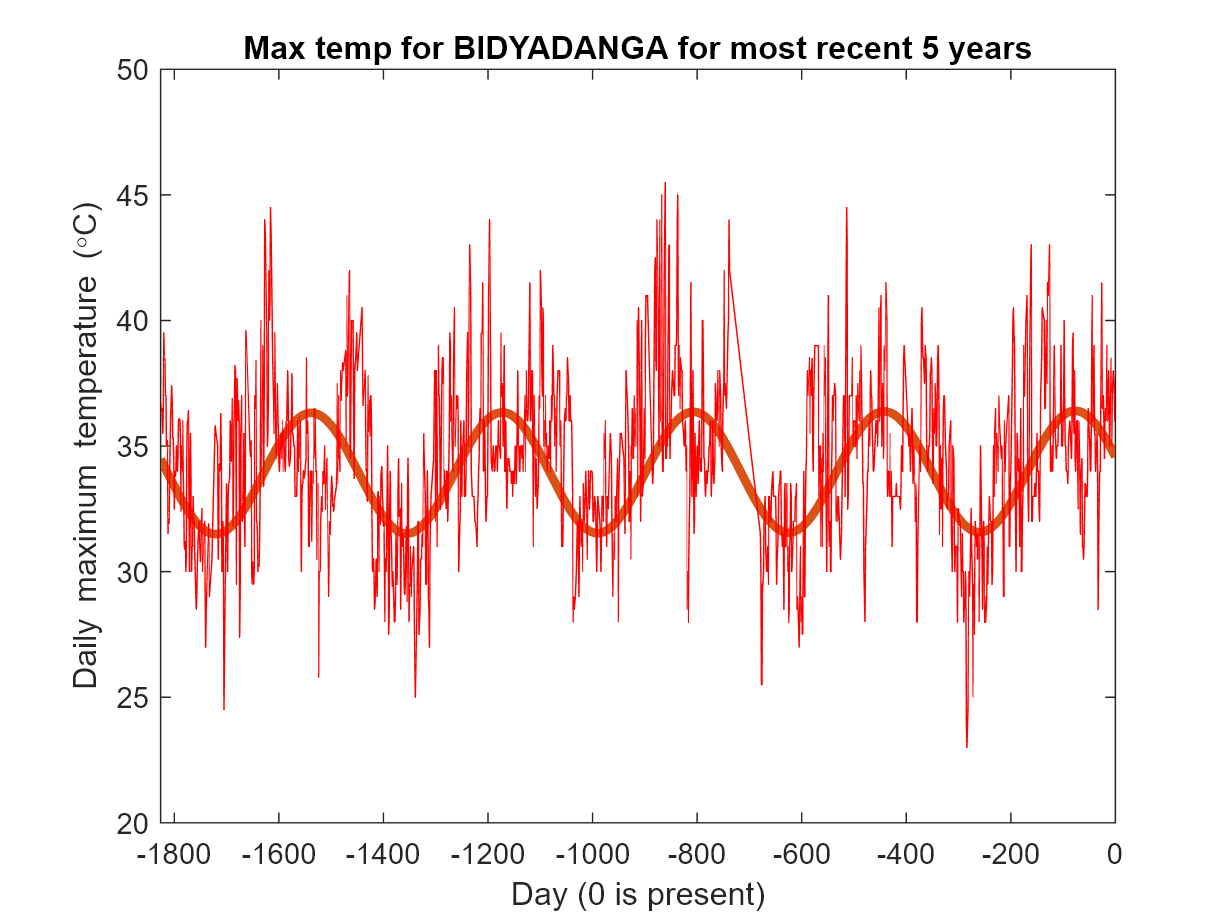

hold on, fplot(@(t_var) t_sol(1)*sin(2 * pi * f * t_var) + t_sol(2)*cos(2 * pi * f * t_var) + t_sol(3)*t_var + t_sol(4),LineWidth=3)
plot(t,ifft(fft(T)), 'r', LineWidth=0.5)

celsius_change_per_day = t_sol(3);
days_per_50_years = 50 * 365.25;
changeIn_50_years = celsius_change_per_day * days_per_50_years

changeIn_50_years =    0.980030332127250


Once you have your model's prediction, **please enter it into the **[**shared Excel spreadsheet**](https://connectqutedu-my.sharepoint.com/:x:/g/personal/moroneyt_qut_edu_au/EdhAiizZI0xCorsLE0-YlTsBAqClUQ--VJcI57pDDoqhpg?e=CSraiD).  The Longreach Aero entry has been prefilled to give you the idea.  Please pay close attention to enter the latitude and longitude values correctly, as well as the temperature.

Meanwhile, your tutor is running a little script that periodically loads the data from this file.  When there are enough entries, a heatmap will begin updating on the main screen.  The more coverage of Australia we get, the more informative the heatmap will be!  So go for it, and if you're done with your location, you can always pick another.  :)

### Group Discussion: What are the limitations?

This investigation is clearly over-simplistic.  Identify as many assumptions or limitations of this investigation as you can that would need further consideration for a fully scientifically rigorous study in the Real World™.

### For the adventurous

We jumped straight into fitting a seasonal variability term to the data.  But should we have thought more about this?  Could there be other oscillatory terms that belong in the model too?

If you're keen, you could take this idea a bit further.  Here are some questions to consider:

- How would you analyse the data to ascertain if there are other oscillatory terms that are significant?  What sort of mathematical tool is useful for uncovering these kinds of oscillatory components in data?

- But your data are not sampled at equally spaced points (there will be gaps corresponding to days of missing data).  Perhaps there is a *nonuniform* version of whatever algorithm you were thinking of?

- If you identify any more terms that look promising, how would you include them in the model?

- Including more terms can't possibly make the fit to the data worse (why?).  But can you quantify by how much the fit has improved?

- How could you decide whether the extra terms are "worth it"?

Following this line of thinking, I calculated a modified fit to the Longreach Aero data shown below.  You can see it's got flatter peaks and sharper troughs than before -- cool!

Do you see the same thing with your data?  Can you explain it?

What effect did changing the model have on your predicted 50-year temperature change?

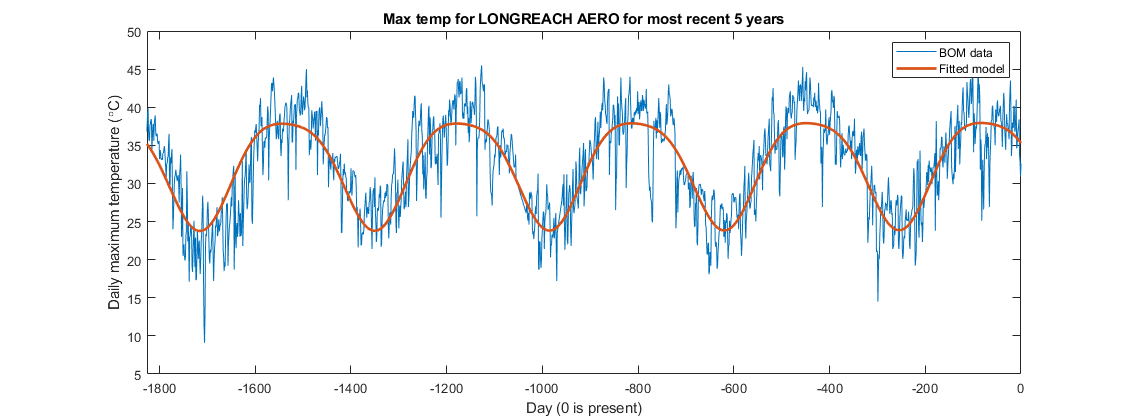

Please feel free to [provide feedback on this week's practical activity](https://forms.office.com/Pages/ResponsePage.aspx?id=o1IL3MVo90SIHZOD2IULlippL5Tej5JHuWnaChxNwu9UMVFNOUpJWDRRUjdIRFZGM1Q0VzRJSlFYVi4u) by clicking the link to an online form.  Feedback is anonymous, and comprises just three questions rating the interest, difficulty and length of the activity.